## Ring Finger Kinematic Analysis

### Read data

clc

table = readtable('linkage_model_data.xlsx');
params = table2array(table(1:40, 5));

[l_01, l_12, l_23, l_30, l_24, l_34, l_45, l_56, l_67, l_73, l_68, l_M8, l_M7, l_59, l_910, l_911, l_1112, l_1113, l_MP, l_PD, l_DF, l_810, l_10P, l_P12, l_D13, l_D12, l_F13, h_0, h_3, h_7, alpha1, alpha2, alpha3, alpha4, beta1, l_M0, l_M3, theta_M0, theta_M3, theta_M7] ...
    = feval(@(x) x{:}, num2cell(params.'));

alpha1  = alpha1 * pi/180;
alpha2  = alpha2 * pi/180;
alpha3  = alpha3 * pi/180;
beta1   = beta1 * pi/180;
alpha4  = alpha4 * pi/180;

e = 0.3;
l_12 = l_12 + e;

e2 = 1.0;
l_68 = l_68 + e2;

e3 = 0;
l_59 = l_59 + e3;

steps = 201;
theta0 = [];

theta1_max = -60;
theta1 = linspace(0, theta1_max, steps);
theta2 = linspace(0, theta1_max * 3/4, steps);
theta3 = linspace(0, theta1_max * 2/4, steps);

M = [0; 0];
K_0 = R(theta_M0 * pi/180) * [l_M0; 0];
K_3 = R(theta_M3 * pi/180) * [l_M3; 0];
K_7 = R(theta_M7 * pi/180) * [l_M7; 0];

### Kinematic Analysis

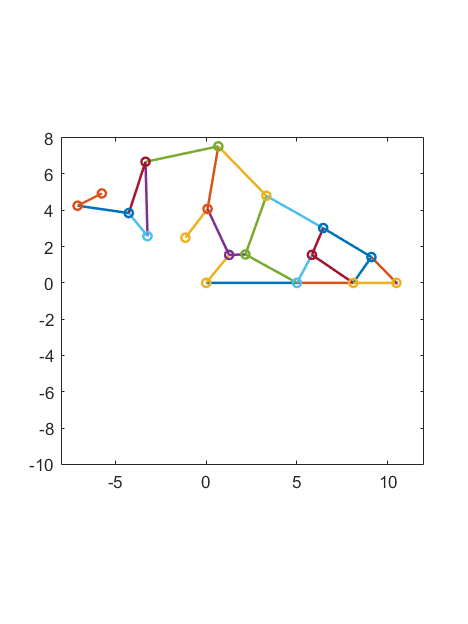

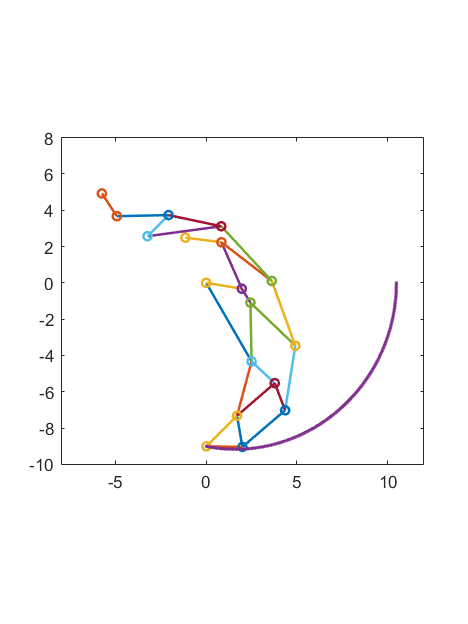

x = [];
y = [];
index = 0;

f = figure();
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,9.9,13.2,14,14,12);
for i = 1:steps
    T_MP = T(theta1(i) * pi/180, l_MP);
    T_PD = T(theta2(i) * pi/180, l_PD);
    T_DF = T(theta3(i) * pi/180, l_DF);
    
    K = [1, 0, 0, 0; 0, 1, 0, 0];
    P = K * T_MP * [0; 0; 0; 1];
    D = K * T_MP * T_PD * [0; 0; 0; 1];
    F = K * T_MP * T_PD * T_DF * [0; 0; 0; 1];
    
    K_8 = (l_M8/l_MP) * R(alpha1) * (P - M) + M;
    K_10 = (l_10P/l_MP) * R(-beta1) * (M - P) + P;
    K_12 = (l_P12/l_PD) * R(alpha2) * (D - P) + P;
    K_13 = (l_D13/l_DF) * R(alpha3) * (F - D) + D;
    
    K_11 = position_analysis(K_13, K_12, l_1113, l_1112, +1);
    K_9 = position_analysis(K_11, K_10, l_911, l_910, +1);
    K_6 = position_analysis(K_7, K_8, l_67, l_68, -1);
    K_5 = position_analysis(K_6, K_9, l_56, l_59, -1);
    K_4 = position_analysis(K_5, K_3, l_45, l_34, +1);
    
    K_2 = (l_23/l_34) * R(alpha4) * (K_4 - K_3) + K_3;
    K_1 = position_analysis(K_0, K_2, l_01, l_12, +1);
    
    v_10 = K_1 - K_0;
    if ~isreal(v_10)
        theta0(i) = NaN;
        continue;
    end
    theta0(i) = atan2(v_10(2), v_10(1)) * 180/pi;
    
    linkMP = [M, P];
    linkPD = [P, D];
    linkDF = [D, F];
    linkM8 = [M, K_8];
    link810 = [K_8, K_10];
    link10P = [K_10, P];
    linkP12 = [P, K_12];
    link12D = [K_12, D];
    linkD13 = [D, K_13];
    link13F = [K_13, F];
    link67 = [K_6, K_7];
    link68 = [K_6, K_8];
    link910 = [K_9, K_10];
    link911 = [K_9, K_11];
    link1112 = [K_11, K_12];
    link1113 = [K_11, K_13];
    link56 = [K_5, K_6];
    link59 = [K_5, K_9];
    link34 = [K_3, K_4];
    link45 = [K_4, K_5];
    link23 = [K_2, K_3];
    link24 = [K_2, K_4];
    link12 = [K_1, K_2];
    link01 = [K_0, K_1];

    index = index + 1;
    x(index) = F(1);
    y(index) = F(2);

    plot(linkMP(1, :), linkMP(2, :),    '-o', ...
        linkPD(1, :), linkPD(2, :),     '-o', ...
        linkM8(1, :), linkM8(2, :),     '-o', ...
        link810(1, :), link810(2, :),   '-o', ...
        link10P(1, :), link10P(2, :),   '-o', ...
        linkP12(1, :), linkP12(2, :),   '-o', ...
        link12D(1, :), link12D(2, :),   '-o', ...
        linkD13(1, :), linkD13(2, :),   '-o', ...
        link13F(1, :), link13F(2, :),   '-o', ...
        link67(1, :), link67(2, :),     '-o', ...
        link68(1, :), link68(2, :),     '-o', ...
        link910(1, :), link910(2, :),   '-o', ...
        link911(1, :), link911(2, :),   '-o', ...
        link1112(1, :), link1112(2, :), '-o', ...
        link1113(1, :), link1113(2, :), '-o', ...
        link56(1, :), link56(2, :),     '-o', ...
        link59(1, :), link59(2, :),     '-o', ...
        link34(1, :), link34(2, :),     '-o', ...
        link45(1, :), link45(2, :),     '-o', ...
        link23(1, :), link23(2, :),     '-o', ...
        link24(1, :), link24(2, :),     '-o', ...
        link12(1, :), link12(2, :),     '-o', ...
        link01(1, :), link01(2, :),     '-o', ...
        linkDF(1, :), linkDF(2, :),     '-o', ...
        x, y, '.', 'MarkerSize', 5, 'LineWidth', 1.5 );
    daspect([1 1 1]);
    xlim([-8 12]);
    ylim([-10 8]);
    pause(0.02);
end

% exportgraphics(f, 'figures/ring_final_a.png', 'Resolution', 600);



theta0_ = theta0.';

theta1_ = theta1.';
for i=1:steps
    if theta0(i) > 0
        theta0(i) = -180 - (180 - theta0(i));
    end
end

%plot(1:steps, theta0, 1:steps, theta1, 1:steps, theta2, 1:steps, theta3);

fprintf("Available range for theta0: [%d, %d]\n", theta0(1), theta0(steps));

Available range for theta0: [-1.531688e+02, -5.674370e+01]


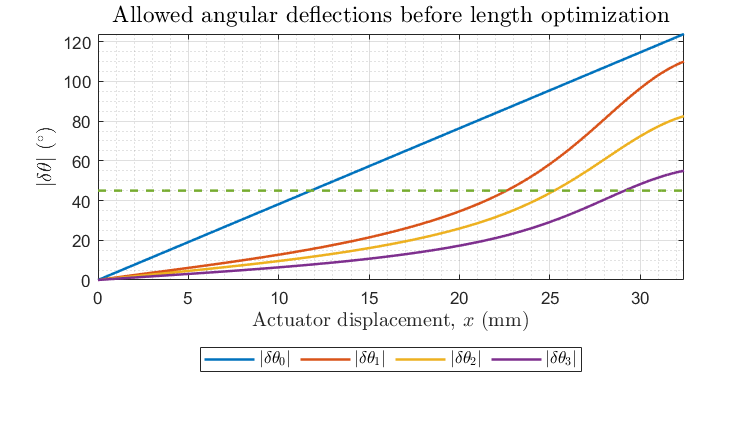

k = find(isnan(theta0_),1) - 1;
if ~isempty(k)
    steps = k;
end
theta0_lin = linspace(theta0(1), theta0(steps), steps);
theta1_lin = [];
theta2_lin = [];
theta3_lin = [];
for i = 1:steps
    j = 1;
    for j = 1:steps
        if theta0(j+1) >= theta0_lin(i)
            break;
        end
    end
    prev = theta0(j);
    next = theta0(j + 1);
    lambda = (theta0_lin(i) - next) / (prev - next);
    theta1_lin(i) = lambda * theta1(j) + (1-lambda) * theta1(j+1);
    theta2_lin(i) = lambda * theta2(j) + (1-lambda) * theta2(j+1);
    theta3_lin(i) = lambda * theta3(j) + (1-lambda) * theta3(j+1);
end

act_disp = [];
theta0_deflection = [];
theta1_deflection = [];
theta2_deflection = [];
theta3_deflection = [];
for i = 1:steps
    act_disp(i) = ((theta0_lin(i) - theta0_lin(1)) * pi/180) * l_01 * 10;
    theta0_deflection(i) = abs(theta0_lin(i) - theta0_lin(1));
    theta1_deflection(i) = abs(theta1_lin(i) - theta1_lin(1));
    theta2_deflection(i) = abs(theta2_lin(i) - theta2_lin(1));
    theta3_deflection(i) = abs(theta3_lin(i) - theta3_lin(1));
end

def_45 = 45 * ones(size(act_disp));

f = figure();
plot(act_disp, theta0_deflection, ...
    act_disp, theta1_deflection, ...
    act_disp, theta2_deflection, ...
    act_disp, theta3_deflection, ...
    act_disp, def_45, '--', 'LineWidth', 1.5);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,14,12,10);
title('Allowed angular deflections before length optimization',title_inputs{:});
xlabel('Actuator displacement, $x$ (mm)',axes_title_inputs{:});
ylabel('$|\delta\theta|$ ($^\circ$)',axes_title_inputs{:});
legend('$|\delta\theta_0|$','$|\delta\theta_1|$','$|\delta\theta_2|$','$|\delta\theta_3|$',legend_inputs{:});

% exportgraphics(f,'figures/ring-deflection-before-range-extension.png','Resolution',600);

global ring_deflection_slope;
ring_deflection_slope = (theta1_deflection(2:end) - theta1_deflection(1:(end-1))) ./ (act_disp(2:end) - act_disp(1:(end-1)));
global ring_act_disp;
ring_act_disp = act_disp(2:end);

val_theta0 = theta0(1) + 76.39;
for i=1:steps
    if theta0(i+1) > val_theta0
        break;
    end
end

prev = theta0(i);
next = theta0(i+1);
lambda = (val_theta0 - next) / (prev - next);

val_theta1 = lambda * theta1(i) + (1 - lambda) * theta1(i+1);
val_theta2 = lambda * theta2(i) + (1 - lambda) * theta2(i+1);
val_theta3 = lambda * theta3(i) + (1 - lambda) * theta3(i+1);

fprintf("theta0 = %d    => [theta1 = %d, theta2 = %d, theta3 = %d]\n", val_theta0, val_theta1, val_theta2, val_theta3);

val_thetaMP = val_theta1;
val_thetaPD = val_thetaMP + val_theta2;
val_thetaDF = val_thetaPD + val_theta3;

fprintf("               => [thetaMP = %d, thetaPD = %d, thetaDF = %d]\n", val_thetaMP, val_thetaPD, val_thetaDF);
fprintf("ratio: thetaDF/thetaMP = %d, thetaPD/thetaMP = %d\n", val_thetaDF/val_thetaMP, val_thetaPD/val_thetaMP);

val_theta2 = 45;
for i=1:steps
    if theta2_deflection(i+1) > val_theta2
        break;
    end
end
prev = theta2_deflection(i);
next = theta2_deflection(i+1);
lambda = (val_theta2 - next) / (prev - next);
val_act_disp = lambda * act_disp(i) + (1-lambda) * act_disp(i+1);
fprintf("theta2 = %d => act_disp = %d\n", val_theta2, val_act_disp);
val_theta0_def = lambda * theta0_deflection(i) + (1-lambda) * theta0_deflection(i+1);
fprintf("theta2 = %d => theta0_disp = %d\n", val_theta2, val_theta0_def);


function M = R(angle)
    M = [ cos(angle), -sin(angle);
          sin(angle), cos(angle) ];
end

function p = position_analysis(p1, p2, l1, l2, sgn)
    R = sqrt( (p2 - p1).' * (p2 - p1) );
    a = (l1^2 - l2^2) / (2 * R^2);
    b = 0.5 * sqrt( 2 * (l1^2+l2^2) / R^2 - (l1^2 - l2^2)^2 / R^4 - 1 );
    
    I = [1, 0; 0, 1];
    B = [0, -1; 1, 0];
    
    p = ( 0.5*[I, I] + (-a*I + sgn*b*B)*[I, -I] ) * [p1; p2];
end

% function p_dot = velocity_analysis(p1, p2, p3, p1_dot, p2_dot)
%     P = [ (p3 - p1).' ; (p3 - p2).' ];
%     p_dot = P \ [ (p3 - p1).' * p1_dot ; (p3 - p2).' * p2_dot ];
% end

% function p_ddot = acceleration_analysis(p1, p2, p3, p1_dot, p2_dot, p3_dot, p1_ddot, p2_ddot)
%     P = [ (p3 - p1).' ; (p3 - p2).' ];
%     q = [ (p3-p1).' * p1_ddot - (p3_dot-p1_dot).' * (p3_dot-p1_dot);
%           (p3-p2).' * p2_ddot - (p3-dot-p2_dot).' * (p3_dot-p2_dot) ];
%     p_ddot = P \ q;
% end

function transf = T(angle, distance)
    transf = [ cos(angle), -sin(angle), 0, distance * cos(angle);
               sin(angle), cos(angle), 0, distance * sin(angle);
               0, 0, 1, 0;
               0, 0, 0, 1 ];
end